## **SECTION 1: TIME VECTOR & DATASET CONFIGURATION**

dt          = 1;            % Sampling interval (hours)
t_end       = 1200;         % Total monitoring duration (hours) ~50 days
time        = (0:dt:t_end); % Time vector [hours]
n           = length(time);

% Phase boundaries (hours)
t_healthy   = 600;   % Normal operation phase ends at 600 h
t_degrade   = 900;   % Accelerated degradation phase ends at 900 h
t_anomaly   = 1050;  % Sudden anomaly event at 1050 h
% Phase 4: 1050–1200 h — post-anomaly / impending failure

## SECTION 2: DATASET GENERATION

% --- Index masks ---
idx_p1 = time <= t_healthy;
idx_p2 = time > t_healthy  & time <= t_degrade;
idx_p3 = time > t_degrade  & time <= t_anomaly;
idx_p4 = time > t_anomaly;

## **SEAL CHAMBER TEMPERATURE**

% -------------------------------------------------------------------------
%  2.1  SEAL CHAMBER TEMPERATURE (°C)
%       Healthy: ~50°C | Alarm threshold: 70°C | Critical: 80°C
% -------------------------------------------------------------------------
temp_base     = 50.0;    % Healthy baseline (°C)
temp_noise    = 0.8;     % Gaussian noise std dev (°C)
temp_drift_p2 = 0.018;   % Linear drift rate, Phase 2 (°C/h)
temp_drift_p3 = 0.045;   % Accelerated drift rate, Phase 3 (°C/h)
temp_step_anom= 14.0;    % Sudden step-up at anomaly event (°C)
temp_drift_p4 = 0.06;    % Post-anomaly drift rate, Phase 4 (°C/h)

seal_chamber_temp = zeros(1, n);

% Phase 1 — healthy baseline
seal_chamber_temp(idx_p1) = temp_base ...
    + temp_noise * randn(1, sum(idx_p1));

% Phase 2 — gradual degradation
t2 = time(idx_p2) - t_healthy;
seal_chamber_temp(idx_p2) = temp_base ...
    + temp_drift_p2 * t2 ...
    + temp_noise * randn(1, sum(idx_p2));

% Phase 3 — accelerated degradation
t2_end_val = temp_base + temp_drift_p2 * (t_degrade - t_healthy);
t3 = time(idx_p3) - t_degrade;
seal_chamber_temp(idx_p3) = t2_end_val ...
    + temp_drift_p3 * t3 ...
    + temp_noise * 1.5 * randn(1, sum(idx_p3));

% Phase 4 — post-anomaly
t3_end_val = t2_end_val + temp_drift_p3 * (t_anomaly - t_degrade);
t4 = time(idx_p4) - t_anomaly;
seal_chamber_temp(idx_p4) = t3_end_val + temp_step_anom ...
    + temp_drift_p4 * t4 ...
    + temp_noise * 2.0 * randn(1, sum(idx_p4));

% Inject minor random spikes (environmental / transient events)
spike_times = randsample(n, 18);
seal_chamber_temp(spike_times) = seal_chamber_temp(spike_times) ...
    + (2.5 + 3.5 * rand(1, 18)) .* sign(randn(1, 18));

## **LEAKAGE RATE**

% -------------------------------------------------------------------------
%  2.2  LEAKAGE RATE (ml/min)
%       Healthy: ~0.8 ml/min | Alarm threshold: 6 ml/min | Critical: 12 ml/min
%       (Regulatory / OEM limit typically 10–15 ml/min for this class)
% -------------------------------------------------------------------------
leak_base     = 0.8;    % Healthy baseline (ml/min)
leak_noise    = 0.15;   % Gaussian noise std dev
leak_drift_p2 = 0.006;  % Linear drift rate, Phase 2 (ml/min/h)
leak_drift_p3 = 0.020;  % Accelerated drift rate, Phase 3
leak_step_anom= 8.0;    % Sudden step-up at anomaly (ml/min)
leak_drift_p4 = 0.035;  % Post-anomaly drift rate

leakage_rate = zeros(1, n);

% Phase 1
leakage_rate(idx_p1) = leak_base ...
    + leak_noise * abs(randn(1, sum(idx_p1)));  % Always positive

% Phase 2
l2 = time(idx_p2) - t_healthy;
leakage_rate(idx_p2) = leak_base ...
    + leak_drift_p2 * l2 ...
    + leak_noise * abs(randn(1, sum(idx_p2)));

% Phase 3
l2_end_val = leak_base + leak_drift_p2 * (t_degrade - t_healthy);
l3 = time(idx_p3) - t_degrade;
leakage_rate(idx_p3) = l2_end_val ...
    + leak_drift_p3 * l3 ...
    + leak_noise * 1.8 * abs(randn(1, sum(idx_p3)));

% Phase 4
l3_end_val = l2_end_val + leak_drift_p3 * (t_anomaly - t_degrade);
l4 = time(idx_p4) - t_anomaly;
leakage_rate(idx_p4) = l3_end_val + leak_step_anom ...
    + leak_drift_p4 * l4 ...
    + leak_noise * 3.0 * abs(randn(1, sum(idx_p4)));

% Clamp to physically meaningful minimum
leakage_rate = max(leakage_rate, 0.1);

## **FLUSH FLOW RATE **

% -------------------------------------------------------------------------
%  2.3  FLUSH FLOW RATE (L/min) — API Plan 11 orifice-controlled flush
%       Healthy: ~4.8 L/min | Alarm if drops below 3.5 or rises above 6.5
% -------------------------------------------------------------------------
flush_base    = 4.8;    % Nominal flush flow (L/min)
flush_noise   = 0.10;   % Gaussian noise std dev
flush_drift   = -0.0015; % Slow drift (partial orifice fouling over time)

flush_flow_rate = flush_base ...
    + flush_drift * time ...
    + flush_noise * randn(1, n);

% Simulate a brief flush line restriction event (t = 400–420 h)
idx_restrict  = time >= 400 & time <= 420;
flush_flow_rate(idx_restrict) = flush_flow_rate(idx_restrict) - 1.2;

% Post-anomaly: reduced flush due to seal face damage
flush_flow_rate(idx_p4) = flush_flow_rate(idx_p4) - 0.4;

flush_flow_rate = max(flush_flow_rate, 1.0);  % Physical lower bound

## **PRESSURE DIFFERENTIAL **

% -------------------------------------------------------------------------
%  2.4  PRESSURE DIFFERENTIAL across seal faces (bar)
%       Healthy: ~2.0 bar | Alarm if > 3.5 bar or < 0.8 bar
% -------------------------------------------------------------------------
press_base    = 2.0;     % Nominal differential (bar)
press_noise   = 0.08;    % Gaussian noise std dev
press_drift   = 0.0008;  % Slow system pressure build-up (bar/h)

pressure_differential = press_base ...
    + press_drift * time ...
    + press_noise * randn(1, n);

% At anomaly: sudden pressure spike then partial relief
pressure_differential(idx_p4) = pressure_differential(idx_p4) + 0.45 ...
    - 0.0002 * (time(idx_p4) - t_anomaly);

% Short transient spike (t = 750 h — process upset)
idx_spike_p = time >= 750 & time <= 760;
pressure_differential(idx_spike_p) = pressure_differential(idx_spike_p) + 0.7;

pressure_differential = max(pressure_differential, 0.2);  % Physical bound

## SECTION 3: THRESHOLD DEFINITIONS

thresholds = struct();

% Seal Chamber Temperature (°C)
thresholds.temp_warn     = 65;   % Warning
thresholds.temp_alarm    = 72;   % Alarm
thresholds.temp_critical = 80;   % Critical / shutdown recommendation

% Leakage Rate (ml/min)
thresholds.leak_warn     = 4.0;
thresholds.leak_alarm    = 6.0;
thresholds.leak_critical = 12.0;

% Flush Flow Rate (L/min)
thresholds.flush_low_warn   = 3.8;   % Low-flow warning
thresholds.flush_low_alarm  = 3.0;   % Low-flow alarm
thresholds.flush_high_warn  = 6.0;   % High-flow warning

% Pressure Differential (bar)
thresholds.press_high_warn  = 3.2;
thresholds.press_high_alarm = 3.8;
thresholds.press_low_alarm  = 0.8;

## SECTION 4: TIME-SERIES PLOTS

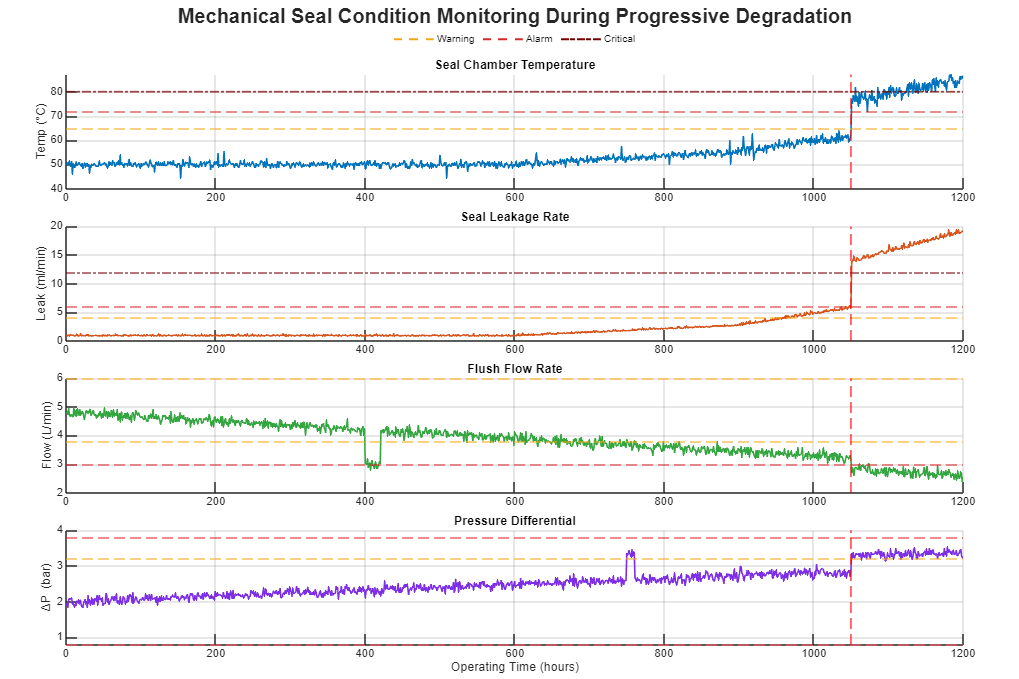

figure('Name','Mechanical Seal Condition Monitoring',...
    'Color','w',...
    'Position',[100 40 1350 900]);

tl = tiledlayout(4,1,...
    'TileSpacing','compact',...
    'Padding','compact');

%% Common colors
cTemp  = [0 0.45 0.74];
cLeak  = [0.85 0.33 0.10];
cFlush = [0.20 0.65 0.25];
cPress = [0.49 0.18 0.90];

warnColor = [0.95 0.65 0.10];
alarmColor = [0.85 0.15 0.15];
criticalColor = [0.45 0 0];

% Temperature

ax1 = nexttile;

hold on
plot(time,seal_chamber_temp,...
    'Color',cTemp,...
    'LineWidth',1.2);

yline(thresholds.temp_warn,'--','Color',warnColor);
yline(thresholds.temp_alarm,'--','Color',alarmColor);
yline(thresholds.temp_critical,'-.','Color',criticalColor,'LineWidth',1.3);

xline(t_anomaly,'r--','LineWidth',1.3);

ylabel('Temp (°C)')
title('Seal Chamber Temperature')

grid on
box off
xlim([0 t_end])

% Leakage
ax2 = nexttile;

hold on

plot(time,leakage_rate,...
    'Color',cLeak,...
    'LineWidth',1.2);

yline(thresholds.leak_warn,'--','Color',warnColor);
yline(thresholds.leak_alarm,'--','Color',alarmColor);
yline(thresholds.leak_critical,'-.','Color',criticalColor);

xline(t_anomaly,'r--','LineWidth',1.3);

ylabel('Leak (ml/min)')
title('Seal Leakage Rate')

grid on
box off
xlim([0 t_end])

% Flush Flow
ax3 = nexttile;

hold on

plot(time,flush_flow_rate,...
    'Color',cFlush,...
    'LineWidth',1.2);

yline(thresholds.flush_low_warn,'--','Color',warnColor);
yline(thresholds.flush_low_alarm,'--','Color',alarmColor);
yline(thresholds.flush_high_warn,'--','Color',warnColor);

xline(t_anomaly,'r--','LineWidth',1.3);

ylabel('Flow (L/min)')
title('Flush Flow Rate')

grid on
box off
xlim([0 t_end])

% Pressure
ax4 = nexttile;

hold on

plot(time,pressure_differential,...
    'Color',cPress,...
    'LineWidth',1.2);

yline(thresholds.press_high_warn,'--','Color',warnColor);
yline(thresholds.press_high_alarm,'--','Color',alarmColor);
yline(thresholds.press_low_alarm,'--','Color',alarmColor);

xline(t_anomaly,'r--','LineWidth',1.3);

ylabel('\DeltaP (bar)')
xlabel('Operating Time (hours)')
title('Pressure Differential')

grid on
box off
xlim([0 t_end])


linkaxes([ax1 ax2 ax3 ax4],'x')

sgtitle('Mechanical Seal Condition Monitoring During Progressive Degradation',...
    'FontWeight','bold',...
    'FontSize',15)
hold on

hWarn = plot(NaN,NaN,'--','Color',warnColor,'LineWidth',1.5);
hAlarm = plot(NaN,NaN,'--','Color',alarmColor,'LineWidth',1.5);
hCritical = plot(NaN,NaN,'-.','Color',criticalColor,'LineWidth',1.5);

lgd = legend([hWarn hAlarm hCritical], ...
    {'Warning','Alarm','Critical'});
lgd.Layout.Tile = 'north';
lgd.Orientation = 'horizontal';
lgd.Box = 'off';

## SECTION 5: CORRELATION ANALYSIS — Temperature vs Leakage Rate

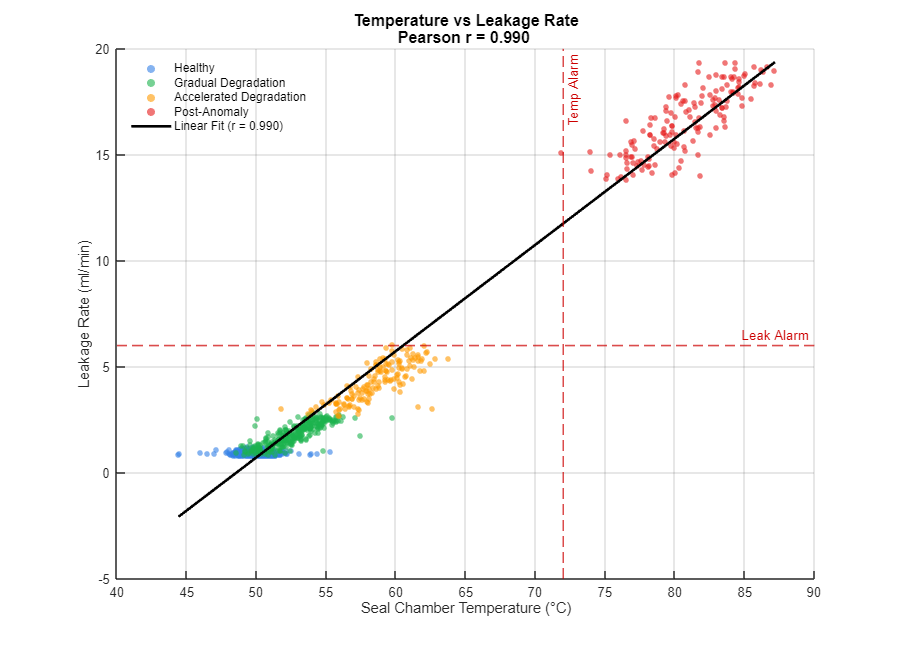

% Pearson correlation
[r_pearson,p_value] = corrcoef(seal_chamber_temp,leakage_rate);

r_val = r_pearson(1,2);
p_val = p_value(1,2);

%% Create Figure

figure('Name','Correlation Analysis',...
    'Position',[100 100 900 650],...
    'Color','w');

hold on

%% Scatter plots for each phase

h1 = scatter(seal_chamber_temp(idx_p1),...
             leakage_rate(idx_p1),...
             18,...
             [0.2 0.5 0.9],...
             'filled',...
             'MarkerFaceAlpha',0.6);

h2 = scatter(seal_chamber_temp(idx_p2),...
             leakage_rate(idx_p2),...
             18,...
             [0.1 0.7 0.3],...
             'filled',...
             'MarkerFaceAlpha',0.6);

h3 = scatter(seal_chamber_temp(idx_p3),...
             leakage_rate(idx_p3),...
             18,...
             [1.0 0.6 0.0],...
             'filled',...
             'MarkerFaceAlpha',0.6);

h4 = scatter(seal_chamber_temp(idx_p4),...
             leakage_rate(idx_p4),...
             18,...
             [0.9 0.1 0.1],...
             'filled',...
             'MarkerFaceAlpha',0.6);

%% Linear regression

p_fit = polyfit(seal_chamber_temp,...
                leakage_rate,...
                1);

x_fit = linspace(min(seal_chamber_temp),...
                 max(seal_chamber_temp),300);

y_fit = polyval(p_fit,x_fit);

hFit = plot(x_fit,...
            y_fit,...
            'k-',...
            'LineWidth',2);

%% Alarm thresholds

xline(thresholds.temp_alarm,...
      '--',...
      'Temp Alarm',...
      'Color',[0.8 0 0],...
      'LineWidth',1.2);

yline(thresholds.leak_alarm,...
      '--',...
      'Leak Alarm',...
      'Color',[0.8 0 0],...
      'LineWidth',1.2);

%% Labels

xlabel('Seal Chamber Temperature (°C)',...
    'FontSize',11);

ylabel('Leakage Rate (ml/min)',...
    'FontSize',11);

title(sprintf('Temperature vs Leakage Rate\nPearson r = %.3f ',...
      r_val),...
      'FontSize',12);

%% Legend

legend([h1 h2 h3 h4 hFit],...
    {'Healthy',...
     'Gradual Degradation',...
     'Accelerated Degradation',...
     'Post-Anomaly',...
     sprintf('Linear Fit (r = %.3f)',r_val)},...
     'Location','northwest',...
     'Box','off');

grid on
box off


%% Print Results

fprintf('\n Correlation Analysis \n');


 Correlation Analysis 


fprintf('Pearson Correlation (r) : %.4f\n',r_val);

Pearson Correlation (r) : 0.9903


if abs(r_val) > 0.8
    fprintf('Interpretation : Strong positive correlation.\n');
elseif abs(r_val) > 0.5
    fprintf('Interpretation : Moderate positive correlation.\n');
else
    fprintf('Interpretation : Weak correlation.\n');
end

Interpretation : Strong positive correlation.


## SECTION 6: TRENDLINE FITTING — Leakage Rate & Temperature

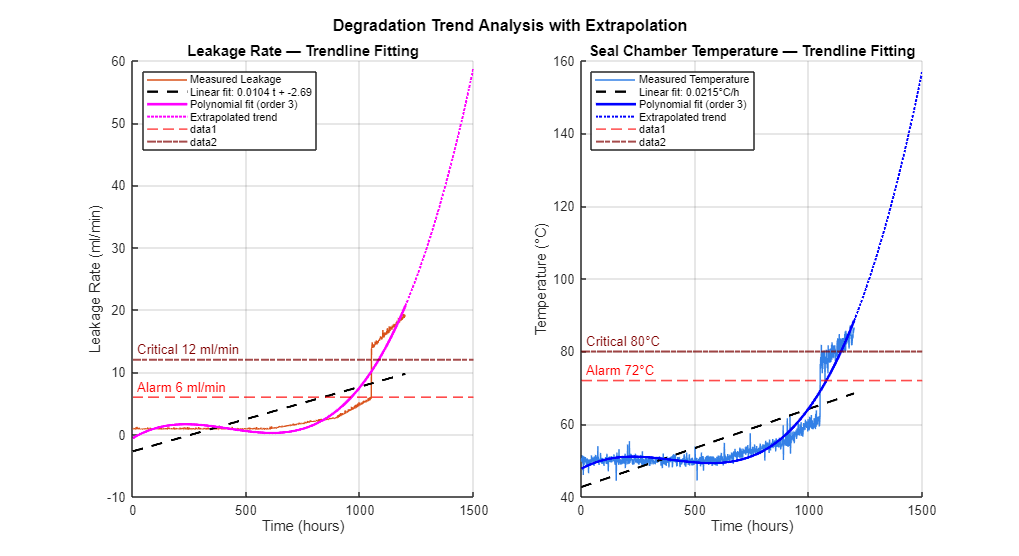

fig3 = figure('Name','Trendline Fitting — Degradation Analysis', ...
    'Position', [150 150 1100 600], 'Color', 'w');

% --- 6.1 Leakage Rate Trendlines ---
subplot(1,2,1);
plot(time, leakage_rate, 'Color', [0.85 0.32 0.1], 'LineWidth', 0.7, ...
    'DisplayName', 'Measured Leakage');
hold on;

% Full-span linear fit
p_leak_lin = polyfit(time, leakage_rate, 1);
leak_lin_fit = polyval(p_leak_lin, time);
plot(time, leak_lin_fit, 'k--', 'LineWidth', 1.8, ...
    'DisplayName', sprintf('Linear fit: %.4f t + %.2f', p_leak_lin(1), p_leak_lin(2)));

% Polynomial (degree-3) fit to capture the accelerating trend
p_leak_poly = polyfit(time, leakage_rate, 3);
leak_poly_fit = polyval(p_leak_poly, time);
plot(time, leak_poly_fit, 'm-', 'LineWidth', 2.0, ...
    'DisplayName', 'Polynomial fit (order 3)');

% Extrapolation to failure
t_extrap = time(end) : dt : time(end) + 300;
leak_extrap = polyval(p_leak_poly, t_extrap);
plot(t_extrap, leak_extrap, 'm:', 'LineWidth', 1.5, ...
    'DisplayName', 'Extrapolated trend');

yline(thresholds.leak_alarm,    '--r', 'Alarm 6 ml/min', 'LineWidth',1.2,'LabelHorizontalAlignment', 'left');
yline(thresholds.leak_critical, '-.', 'color',[0.5 0 0], 'LineWidth',1.5, ...
    'Label','Critical 12 ml/min','LabelHorizontalAlignment', 'left');

xlabel('Time (hours)'); ylabel('Leakage Rate (ml/min)');
title('Leakage Rate — Trendline Fitting'); grid on; box off;
legend('Location','northwest','FontSize',8);
xlim([0 time(end)+300]);

% --- 6.2 Temperature Trendlines ---
subplot(1,2,2);
plot(time, seal_chamber_temp, 'Color', [0.2 0.5 0.9], 'LineWidth', 0.7, ...
    'DisplayName', 'Measured Temperature');
hold on;

p_temp_lin = polyfit(time, seal_chamber_temp, 1);
temp_lin_fit = polyval(p_temp_lin, time);
plot(time, temp_lin_fit, 'k--', 'LineWidth', 1.8, ...
    'DisplayName', sprintf('Linear fit: %.4f°C/h', p_temp_lin(1)));

p_temp_poly = polyfit(time, seal_chamber_temp, 3);
temp_poly_fit = polyval(p_temp_poly, time);
plot(time, temp_poly_fit, 'b-', 'LineWidth', 2.0, ...
    'DisplayName', 'Polynomial fit (order 3)');

temp_extrap = polyval(p_temp_poly, t_extrap);
plot(t_extrap, temp_extrap, 'b:', 'LineWidth', 1.5, ...
    'DisplayName', 'Extrapolated trend');

yline(thresholds.temp_alarm,    '--r', 'Alarm 72°C',    'LineWidth',1.2,'LabelHorizontalAlignment', 'left');
yline(thresholds.temp_critical, '-.', 'color',[0.5 0 0], 'LineWidth',1.5, ...
    'Label','Critical 80°C','LabelHorizontalAlignment', 'left');

xlabel('Time (hours)'); ylabel('Temperature (°C)');
title('Seal Chamber Temperature — Trendline Fitting'); grid on; box off;
legend('Location','northwest','FontSize',8);
xlim([0 time(end)+300]);

sgtitle('Degradation Trend Analysis with Extrapolation', ...
    'FontSize', 12, 'FontWeight', 'bold');


% Compute linear degradation rates for reporting
fprintf('\n--- TRENDLINE FITTING RESULTS ---\n');


--- TRENDLINE FITTING RESULTS ---


fprintf('  Leakage Rate — Linear slope  : %.5f ml/min per hour\n', p_leak_lin(1));

  Leakage Rate — Linear slope  : 0.01037 ml/min per hour


fprintf('  Temperature  — Linear slope  : %.5f °C per hour\n', p_temp_lin(1));

  Temperature  — Linear slope  : 0.02148 °C per hour


## SECTION 7: THRESHOLD-BASED ALARM DETECTION

fprintf(' THRESHOLD-BASED ALARM REPORT\n');

 THRESHOLD-BASED ALARM REPORT


%% Helper function
printAlarm = @(idx,label,limit,unit) ...
    fprintf('  %-10s (%s %.1f %s) : %4d samples | First = %5.0f h | Last = %5.0f h\n',...
    label,...
    limit.sign,...
    limit.value,...
    unit,...
    numel(idx),...
    time(idx(1)),...
    time(idx(end)));

% TEMPERATURE
fprintf('\n[TEMPERATURE]\n');


[TEMPERATURE]



alarms = {
    find(seal_chamber_temp > thresholds.temp_warn),     'WARNING',  struct('sign','>','value',thresholds.temp_warn);
    find(seal_chamber_temp > thresholds.temp_alarm),    'ALARM',    struct('sign','>','value',thresholds.temp_alarm);
    find(seal_chamber_temp > thresholds.temp_critical), 'CRITICAL', struct('sign','>','value',thresholds.temp_critical);
};

for k = 1:size(alarms,1)

    idx = alarms{k,1};

    if ~isempty(idx)
        printAlarm(idx,alarms{k,2},alarms{k,3},'°C');
    end

end

  WARNING    (> 65.0 °C) :  150 samples | First =  1051 h | Last =  1200 h
  ALARM      (> 72.0 °C) :  149 samples | First =  1051 h | Last =  1200 h
  CRITICAL   (> 80.0 °C) :   88 samples | First =  1056 h | Last =  1200 h


% LEAKAGE
fprintf('\n[LEAKAGE RATE]\n');


[LEAKAGE RATE]



alarms = {
    find(leakage_rate > thresholds.leak_warn),     'WARNING',  struct('sign','>','value',thresholds.leak_warn);
    find(leakage_rate > thresholds.leak_alarm),    'ALARM',    struct('sign','>','value',thresholds.leak_alarm);
    find(leakage_rate > thresholds.leak_critical), 'CRITICAL', struct('sign','>','value',thresholds.leak_critical);
};

for k = 1:size(alarms,1)
    idx = alarms{k,1};
    if ~isempty(idx)
        printAlarm(idx,alarms{k,2},alarms{k,3},'ml/min');
    end
end

  WARNING    (> 4.0 ml/min) :  240 samples | First =   949 h | Last =  1200 h
  ALARM      (> 6.0 ml/min) :  151 samples | First =  1048 h | Last =  1200 h
  CRITICAL   (> 12.0 ml/min) :  150 samples | First =  1051 h | Last =  1200 h


% FLUSH FLOW
fprintf('\n[FLUSH FLOW RATE]\n');


[FLUSH FLOW RATE]



alarms = {
    find(flush_flow_rate < thresholds.flush_low_warn),  'LOW WARNING', struct('sign','<','value',thresholds.flush_low_warn);
    find(flush_flow_rate < thresholds.flush_low_alarm), 'LOW ALARM',   struct('sign','<','value',thresholds.flush_low_alarm);
    find(flush_flow_rate > thresholds.flush_high_warn), 'HIGH WARNING',struct('sign','>','value',thresholds.flush_high_warn);
};

for k = 1:size(alarms,1)
    idx = alarms{k,1};
    if ~isempty(idx)
        printAlarm(idx,alarms{k,2},alarms{k,3},'L/min');
    end
end

  LOW WARNING (< 3.8 L/min) :  564 samples | First =   400 h | Last =  1200 h
  LOW ALARM  (< 3.0 L/min) :  158 samples | First =   402 h | Last =  1200 h




% PRESSURE
fprintf('\n[PRESSURE DIFFERENTIAL]\n');


[PRESSURE DIFFERENTIAL]



alarms = {
    find(pressure_differential > thresholds.press_high_warn),  'HIGH WARNING', struct('sign','>','value',thresholds.press_high_warn);
    find(pressure_differential > thresholds.press_high_alarm), 'HIGH ALARM',   struct('sign','>','value',thresholds.press_high_alarm);
    find(pressure_differential < thresholds.press_low_alarm),  'LOW ALARM',    struct('sign','<','value',thresholds.press_low_alarm);
};

for k = 1:size(alarms,1)
    idx = alarms{k,1};
    if ~isempty(idx)
        printAlarm(idx,alarms{k,2},alarms{k,3},'bar');
    end
end

  HIGH WARNING (> 3.2 bar) :  154 samples | First =   750 h | Last =  1200 h


## SECTION 8: COMBINED ALARM STATUS DASHBOARD PLOT

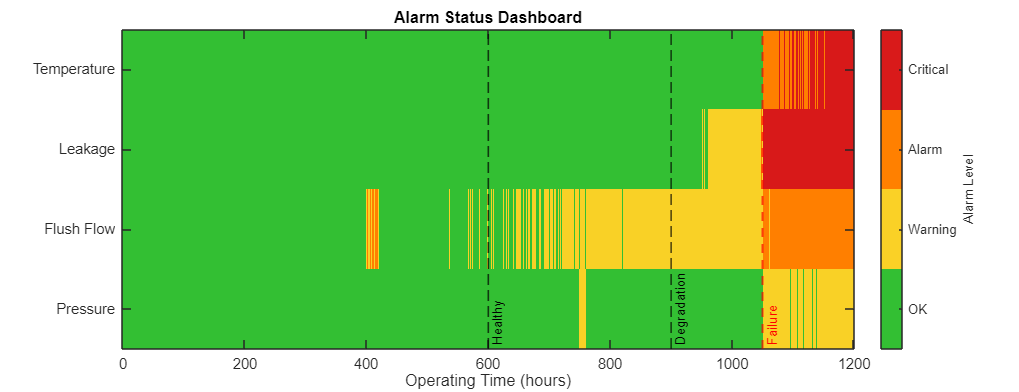

fig4 = figure('Name','Alarm Status Dashboard',...
    'Position',[200 200 1300 500],...
    'Color','w');

%% Build alarm level vectors
% 0 = OK
% 1 = Warning
% 2 = Alarm
% 3 = Critical

%% Alarm indices
% Temperature
idx_temp_warn     = seal_chamber_temp > thresholds.temp_warn;
idx_temp_alarm    = seal_chamber_temp > thresholds.temp_alarm;
idx_temp_critical = seal_chamber_temp > thresholds.temp_critical;

% Leakage
idx_leak_warn     = leakage_rate > thresholds.leak_warn;
idx_leak_alarm    = leakage_rate > thresholds.leak_alarm;
idx_leak_critical = leakage_rate > thresholds.leak_critical;

% Flush Flow
idx_flush_low_warn  = flush_flow_rate < thresholds.flush_low_warn;
idx_flush_low_alarm = flush_flow_rate < thresholds.flush_low_alarm;
idx_flush_high_warn = flush_flow_rate > thresholds.flush_high_warn;

% Pressure
idx_press_high_warn  = pressure_differential > thresholds.press_high_warn;
idx_press_high_alarm = pressure_differential > thresholds.press_high_alarm;
idx_press_low_alarm  = pressure_differential < thresholds.press_low_alarm;
alarm_temp = zeros(1,n);

alarm_temp(idx_temp_warn)     = 1;
alarm_temp(idx_temp_alarm)    = 2;
alarm_temp(idx_temp_critical) = 3;

alarm_leak = zeros(1,n);

alarm_leak(idx_leak_warn)     = 1;
alarm_leak(idx_leak_alarm)    = 2;
alarm_leak(idx_leak_critical) = 3;

alarm_flush = zeros(1,n);

alarm_flush(idx_flush_low_warn)  = 1;
alarm_flush(idx_flush_low_alarm) = 2;

alarm_press = zeros(1,n);

% High pressure
alarm_press(idx_press_high_warn)  = 1;
alarm_press(idx_press_high_alarm) = 2;

% Low pressure alarm
alarm_press(idx_press_low_alarm) = 2;

%% Alarm matrix
alarm_matrix = [
    alarm_temp;
    alarm_leak;
    alarm_flush;
    alarm_press];

%% Discrete colour map
alarm_cmap = [
    0.20 0.75 0.20     % Green     -> OK
    0.98 0.82 0.15     % Yellow    -> Warning
    1.00 0.50 0.00     % Orange    -> Alarm
    0.85 0.10 0.10];   % Red       -> Critical

imagesc(time,1:4,alarm_matrix);

colormap(alarm_cmap);

% Force discrete colour bins
clim([-0.5 3.5]);

set(gca,...
    'YTick',1:4,...
    'YTickLabel',{'Temperature','Leakage','Flush Flow','Pressure'},...
    'Layer','top',...
    'FontSize',11);

xlabel('Operating Time (hours)');
title('Alarm Status Dashboard');

hold on

%% Phase boundaries
xline(t_healthy,...
    '--k',...
    'Healthy',...
    'LineWidth',1.2,...
    'LabelVerticalAlignment','bottom');

xline(t_degrade,...
    '--k',...
    'Degradation',...
    'LineWidth',1.2,...
    'LabelVerticalAlignment','bottom');

xline(t_anomaly,...
    '--r',...
    'Failure',...
    'LineWidth',1.5,...
    'LabelVerticalAlignment','bottom');

%% Colorbar
cb = colorbar;

cb.Ticks = [0 1 2 3];
cb.TickLabels = {'OK','Warning','Alarm','Critical'};
cb.Label.String = 'Alarm Level';

box on
grid off

## SECTION 9: REMAINING USEFUL LIFE (RUL) ESTIMATION

%% ========================================================================
% SECTION 9 : REMAINING USEFUL LIFE (RUL) VALIDATION
% Predictions at 900 h and 1050 h
%% ========================================================================

prediction_times = [900 1050];

polyOrder = 3;
tol = 1e-8;

% Actual failure times from complete dataset
actualLeakFailure = time(find(leakage_rate >= thresholds.leak_critical,1,'first'));
actualTempFailure = time(find(seal_chamber_temp >= thresholds.temp_critical,1,'first'));

fprintf('\n');
fprintf('===============================================================\n');

fprintf('      REMAINING USEFUL LIFE (RUL) VALIDATION\n');

      REMAINING USEFUL LIFE (RUL) VALIDATION


fprintf('===============================================================\n');


fprintf('\nActual Failure Times\n');


Actual Failure Times


fprintf('-----------------------------\n');

-----------------------------


fprintf('Leakage     : %.0f h\n',actualLeakFailure);

Leakage     : 1051 h


fprintf('Temperature : %.0f h\n',actualTempFailure);

Temperature : 1056 h



for k = 1:length(prediction_times)

    prediction_time = prediction_times(k);

    fprintf('\n===============================================================\n');
    fprintf('Prediction performed at %.0f hours\n',prediction_time);
    fprintf('===============================================================\n');

    %% Use only data available up to prediction time

    idx_fit = (time >= t_healthy) & (time <= prediction_time);

    time_fit = time(idx_fit);

    leak_fit = leakage_rate(idx_fit);
    temp_fit = seal_chamber_temp(idx_fit);

    %% Polynomial models

    pLeak = polyfit(time_fit,leak_fit,polyOrder);
    pTemp = polyfit(time_fit,temp_fit,polyOrder);

    %% ---------------- Leakage ----------------

    coeff = pLeak;
    coeff(end) = coeff(end) - thresholds.leak_critical;

    r = roots(coeff);

    valid = real(r(abs(imag(r))<tol & real(r)>prediction_time));

    if isempty(valid)

        tFailLeak = NaN;
        RULLeak = NaN;
        leakError = NaN;

    else

        tFailLeak = min(valid);
        RULLeak = tFailLeak - prediction_time;
        leakError = tFailLeak - actualLeakFailure;

    end

    %% ---------------- Temperature ----------------

    coeff = pTemp;
    coeff(end) = coeff(end) - thresholds.temp_critical;

    r = roots(coeff);

    valid = real(r(abs(imag(r))<tol & real(r)>prediction_time));

    if isempty(valid)

        tFailTemp = NaN;
        RULTemp = NaN;
        tempError = NaN;

    else

        tFailTemp = min(valid);
        RULTemp = tFailTemp - prediction_time;
        tempError = tFailTemp - actualTempFailure;

    end

    %% Overall RUL

    overallRUL = min([RULLeak RULTemp],[],'omitnan');

    %% Report

    fprintf('\n%-15s %-15s %-15s %-15s\n',...
        'Indicator','Actual(h)','Predicted(h)','Error(h)');

    fprintf('---------------------------------------------------------------\n');

    fprintf('%-15s %-15.0f %-15.0f %-15.1f\n',...
        'Leakage',...
        actualLeakFailure,...
        tFailLeak,...
        leakError);

    fprintf('%-15s %-15.0f %-15.0f %-15.1f\n',...
        'Temperature',...
        actualTempFailure,...
        tFailTemp,...
        tempError);

    fprintf('---------------------------------------------------------------\n');

    fprintf('\n');

    fprintf('Leakage RUL     : %.0f h (%.1f days)\n',...
        RULLeak,RULLeak/24);

    fprintf('Temperature RUL : %.0f h (%.1f days)\n',...
        RULTemp,RULTemp/24);

    fprintf('Overall RUL     : %.0f h (%.1f days)\n',...
        overallRUL,overallRUL/24);

    %% Maintenance recommendation

    if isnan(overallRUL)

        fprintf('\nRecommendation : Unable to estimate RUL.\n');

    elseif overallRUL <= 200

        fprintf('\nRecommendation : Schedule maintenance immediately.\n');
        fprintf('Failure can be avoided if maintenance is performed before %.0f h.\n',...
            prediction_time + overallRUL);

    else

        fprintf('\nRecommendation : Continue monitoring.\n');

    end

end

Prediction performed at 900 hours



Indicator       Actual(h)       Predicted(h)    Error(h)       


---------------------------------------------------------------


Leakage         1051            NaN             NaN            


Temperature     1056            NaN             NaN            


---------------------------------------------------------------


Leakage RUL     : NaN h (NaN days)


Temperature RUL : NaN h (NaN days)


Overall RUL     : NaN h (NaN days)



Recommendation : Unable to estimate RUL.


Prediction performed at 1050 hours



Indicator       Actual(h)       Predicted(h)    Error(h)       


---------------------------------------------------------------


Leakage         1051            1190            138.9          


Temperature     1056            1263            206.7          


---------------------------------------------------------------


Leakage RUL     : 140 h (5.8 days)


Temperature RUL : 213 h (8.9 days)


Overall RUL     : 140 h (5.8 days)



Recommendation : Schedule maintenance immediately.


Failure can be avoided if maintenance is performed before 1190 h.
